Esercizio 1

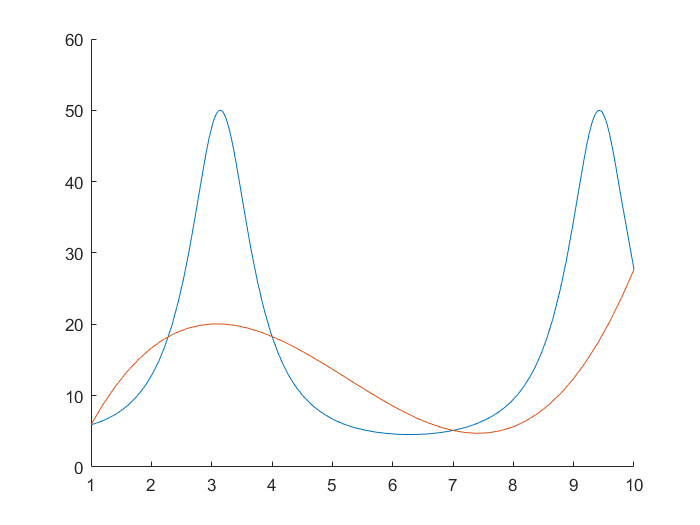

f=@(x) 1./((exp(x+0.2)-1).^2+0.05)+10./(cos(x)+1.2);
n=1:3:10;
y=f(n);
p3=polyfit(n,y,3);
figure()
hold on
fplot(f,[1 10])
v=polyval(p3,1:0.2:10);
plot(1:0.2:10,v)

nerr=2.5:3:8.5;

err=norm(f(nerr)-polyval(p3,nerr),inf)

err = 8.6156